% 使用线性支持向量机分析图像
% 此示例说明如何通过训练由线性 SVM 二类学习器组成的纠错输出编码 (ECOC) 模型
% 来确定形状占据图像的哪个象限。
% 此示例还说明存储支持向量、其标签和估计的 α 系数的 ECOC 模型的磁盘空间消耗。
% 

## 创建数据集

在一个 50×50 图像中随机放置一个半径为 5 的圆。 生成 5000 个图像。为每个图像创建一个标签，指示圆占据的象限。 象限 1 在右上角，象限 2 在左上角，象限 3 在左下角，象限 4 在右下角。 预测变量是每个像素的强度。

d = 50;  % Height and width of the images in pixels
n = 5e4; % Sample size

X = zeros(n,d^2); % Predictor matrix preallocation 
Y = zeros(n,1);   % Label preallocation
theta = 0:(1/d):(2*pi);
r = 5;            % Circle radius
rng(1);           % For reproducibility

for j = 1:n
    figmat = zeros(d);                       % Empty image
    c = datasample((r + 1):(d - r - 1),2);   % Random circle center
    x = r*cos(theta) + c(1);                 % Make the circle 
    y = r*sin(theta) + c(2);               
    idx = sub2ind([d d],round(y),round(x));  % Convert to linear indexing
    figmat(idx) = 1;                         % Draw the circle
    X(j,:) = figmat(:);                % Store the data
    Y(j) = (c(2) >= floor(d/2)) + 2*(c(2) < floor(d/2)) + ...
        (c(1) < floor(d/2)) + ...
        2*((c(1) >= floor(d/2)) & (c(2) < floor(d/2))); % Determine the quadrant
end

## 绘制观测值。

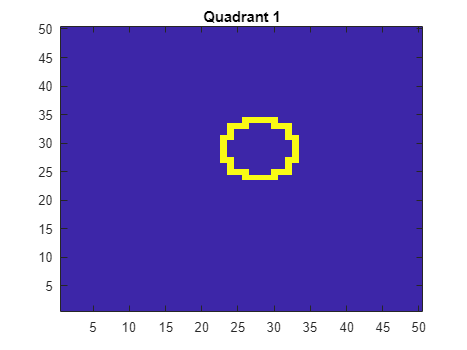

figure
imagesc(figmat)
h = gca;
h.YDir = 'normal';
title(sprintf('Quadrant %d',Y(end)))

## 训练 ECOC 模型

使用 25% 的留出样本，并指定训练和留出样本索引。

p = 0.25;
CVP = cvpartition(Y,'Holdout',p); % Cross-validation data partition
isIdx = training(CVP);            % Training sample indices
oosIdx = test(CVP);               % Test sample indices
% 创建一个 SVM 模板，它指定存储二类学习器的支持向量。
% 将它和训练数据传递给 fitcecoc 以训练模型。确定训练样本分类误差。

t = templateSVM('SaveSupportVectors',true);
MdlSV = fitcecoc(X(isIdx,:),Y(isIdx),'Learners',t);
isLoss = resubLoss(MdlSV)   % isLoss = 0

isLoss = 0

% MdlSV 是经过训练的 ClassificationECOC 多类模型。它存储每个二类学习器的训练数据和支持向量。对于大型数据集，如图像分析中的数据集，该模型会消耗大量内存。

% 确定 ECOC 模型消耗的磁盘空间量。

infoMdlSV = whos('MdlSV');
mbMdlSV = infoMdlSV.bytes/1.049e6  % mbMdlSV = 763.6150

mbMdlSV = 763.6163

% 该模型消耗 763.6 MB。

## 提高模型效率

您可以评估样本外的性能。您还可以使用不包含支持向量、 其相关参数和训练数据的压缩模型来评估模型是否过拟合。 从经过训练的 ECOC 模型中丢弃支持向量和相关参数。 然后，使用 compact 从生成的模型中丢弃训练数据。

Mdl = discardSupportVectors(MdlSV);
CMdl = compact(Mdl);
info = whos('Mdl','CMdl');
[bytesCMdl,bytesMdl] = info.bytes;
memReduction = 1 - [bytesMdl bytesCMdl]/infoMdlSV.bytes

memReduction =     0.0626    0.9996


% memReduction = 1×2
%     0.0626    0.9996

% 在本例中，丢弃支持向量可将内存消耗减少大约 6%。
% 压缩和丢弃支持向量会将大小减小大约 99.96%。
% 管理支持向量的另一种方法是通过指定更大的框约束（如 100）
% 来减少训练过程中的支持向量数量。
% 虽然使用更少支持向量的 SVM 模型更可取并且消耗更少的内存，
% 但增加框约束的值往往会增加训练时间。
% 从工作区中删除 MdlSV 和 Mdl。

clear Mdl MdlSV

## 评估留出样本性能

计算留出样本的分类误差。绘制留出样本预测的样本。

oosLoss = loss(CMdl,X(oosIdx,:),Y(oosIdx))

oosLoss = 0

oosLoss = 0

oosLoss = 0

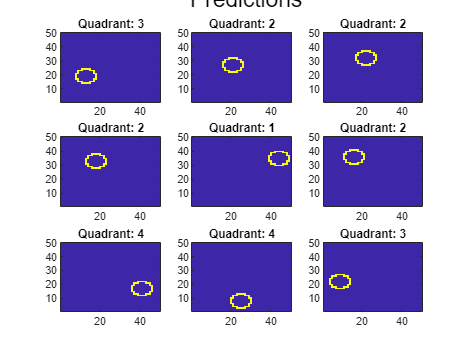

yHat = predict(CMdl,X(oosIdx,:));
nVec = 1:size(X,1);
oosIdx = nVec(oosIdx);

figure;
for j = 1:9
    subplot(3,3,j)
    imagesc(reshape(X(oosIdx(j),:),[d d]))
    h = gca;
    h.YDir = 'normal';
    title(sprintf('Quadrant: %d',yHat(j)))
end
text(-1.33*d,4.5*d + 1,'Predictions','FontSize',17)


% 该模型不会对任何留出样本观测值进行误分类。